# Exergy Cost Calculator Demo

Use ExergyCostCalculator function to compute direct and generalized exergy cost

#### Select the model file

Use uigetfile control to select the model file

file='cgam_model.xlsx';
data=ReadDataModel(file);

#### Select the parameters

States=convertCharsToStrings(data.States);
State=convertStringsToChars(States(1));
Samples=convertCharsToStrings(data.ResourceSamples);
ResourceSample=convertStringsToChars(Samples(1));

#### Compute the Exergy Cost

res=ExergyCostCalculator(data,'State',State,...
    'CostTables','ALL',...
    'ResourceSample',ResourceSample);
printResults(res);

Waste Allocation Table  (%)

 Key          QG
-----------------
 COMB     100.00


Flows Exergy Cost

 Key  B(MW)       B*(MW)      Be*(MW)     Br*(MW)     k*(J/J)     ke*(J/J)    kr*(J/J)   
------------------------------------------------------------------------------------------
 NG        82.711      82.711      82.711       0.000      1.0000      1.0000      0.0000
 B1         0.000       0.000       0.000       0.000      0.0000      0.0000      0.0000
 B2        28.511      55.037      52.773       2.263      1.9304      1.8510      0.0794
 B3        47.246      90.541      86.818       3.723      1.9164      1.8376      0.0788
 B4       104.268     176.800     169.529       7.271      1.6956      1.6259      0.0697
 B5        40.496      68.666      65.842       2.824      1.6956      1.6259      0.0697
 B6        19.557      33.161      31.798       1.364      1.6956      1.6259      0.0697
 B7         2.092       3.547       3.401       0.146      1.6956      1.6259      0.06

#### Show Irreversibility Cost Graph

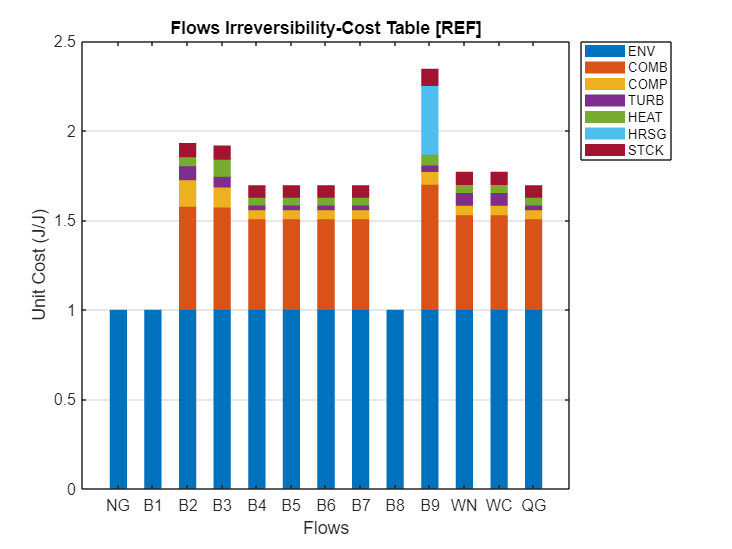

graphCost(res,cType.Tables.FLOW_ICT);